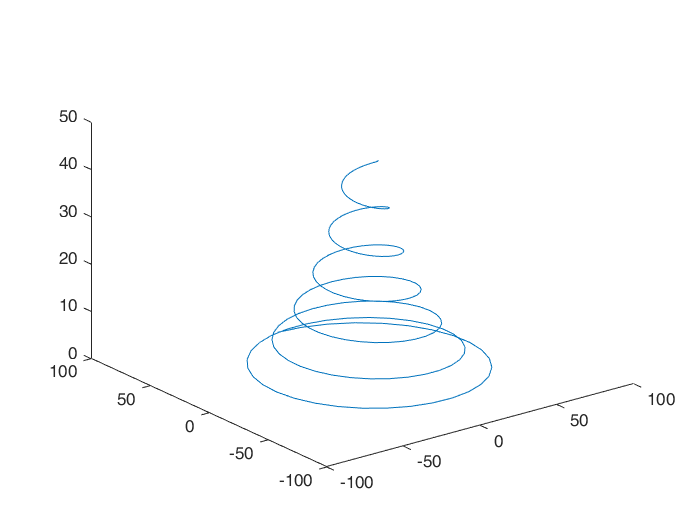

%1
t=0:0.1:20;
x=(0.01*(30-t).^2).*(8*sin(2*t));
y=(0.01*(30-t).^2).*(8*cos(2*t));
z=0.5*t.^1.5;
plot3(x,y,z)

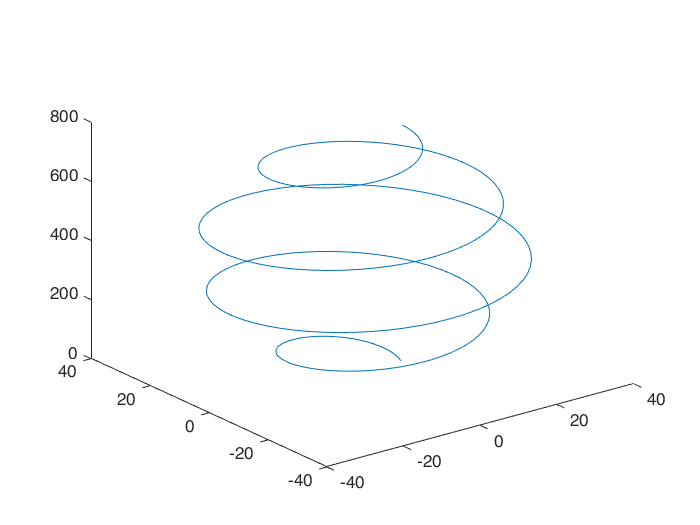

%2
close all
n=4;
t=0:0.1:2*pi*n;
h=50;
r=h*(2+5*sin(t/8))/10;
x=r.*cos(t);
y=r.*sin(t);
z=(h*t)/(2*pi/n);
axis([-50 50 -50 50 0 60]);
plot3(x,y,z)

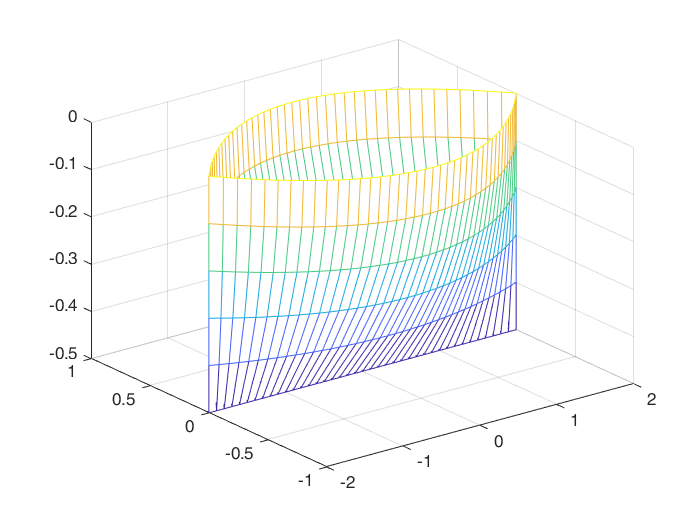

%3
B=1.2;
L=4;
T=0.5;
x=-2:0.1:2;
z=-0.5:0.1:0;
[X,Z]=meshgrid(x,z);
Y=(B/2).*(1-(2*X./L).^2).*(1-(Z./T).^2);
YP=-(B/2).*(1-(2*X./L).^2).*(1-(Z./T).^2);
mesh(X,Y,Z)
hold on
mesh(X,YP,Z)

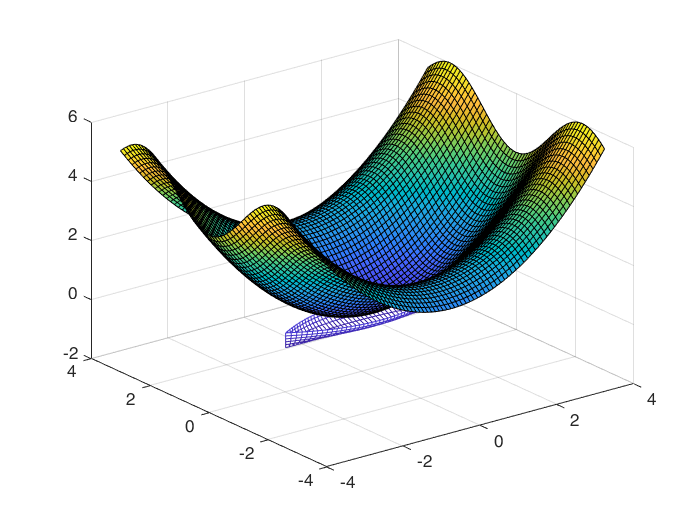

%4
x=-4:0.1:4;
y=-3:0.1:3;
[X,Y]=meshgrid(x,y);
Z=(X.^2)/4+2*sin(0.7*Y).^2;
surf(X,Y,Z)

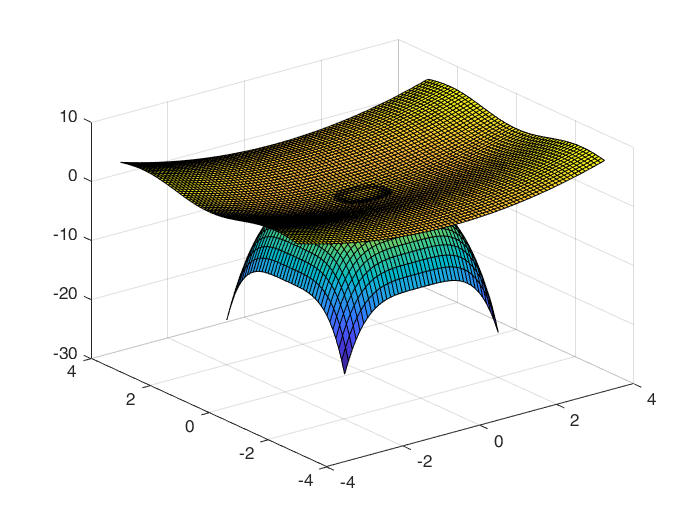

%5
x=-2:0.1:2;
y=-2:0.1:2;
[X,Y]=meshgrid(x,y);
Z=-0.7*(X.^4)-0.7*(Y.^4);
surf(X,Y,Z)

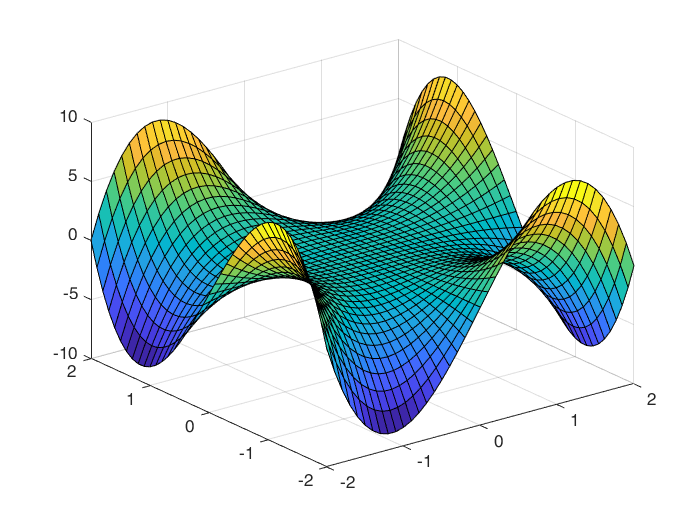

%6
close all
x=-2:0.1:2;
y=-2:0.1:2;
[X,Y]=meshgrid(x,y);
Z=-1.4*X.*(Y.^3)+1.4*Y.*(X.^3);
surf(X,Y,Z)

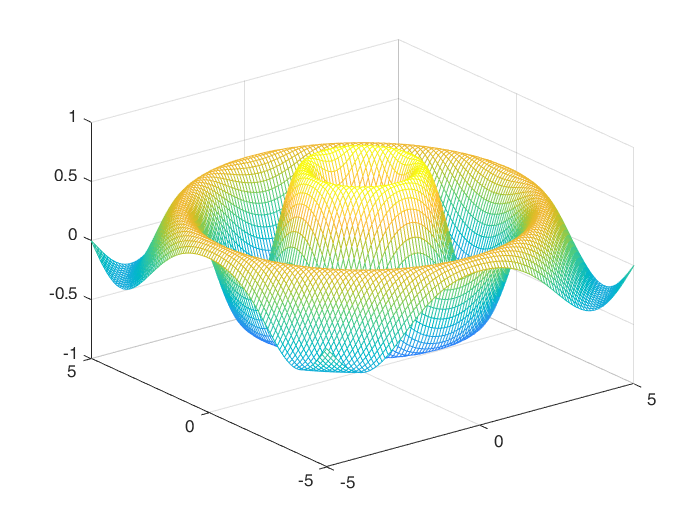

%7
close all
x=-5:0.1:5;
y=-5:0.1:5;
[X,Y]=meshgrid(x,y);
R=sqrt(X.^2+Y.^2);
Z=-cos(2*R)./exp(0.2*R);
mesh(X,Y,Z)

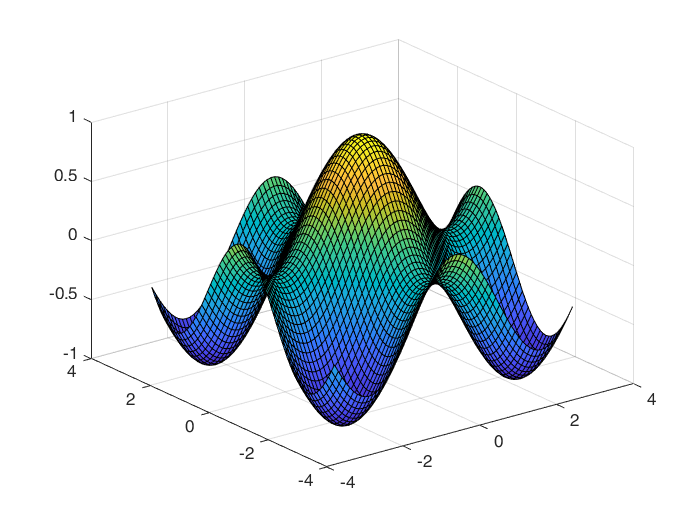

%8
close all
x=-pi:0.1:pi;
y=-pi:0.1:pi;
[X,Y]=meshgrid(x,y);
Z=cos(0.7*X+0.7*Y).*cos(0.7*X-0.7*Y);
surf(X,Y,Z)

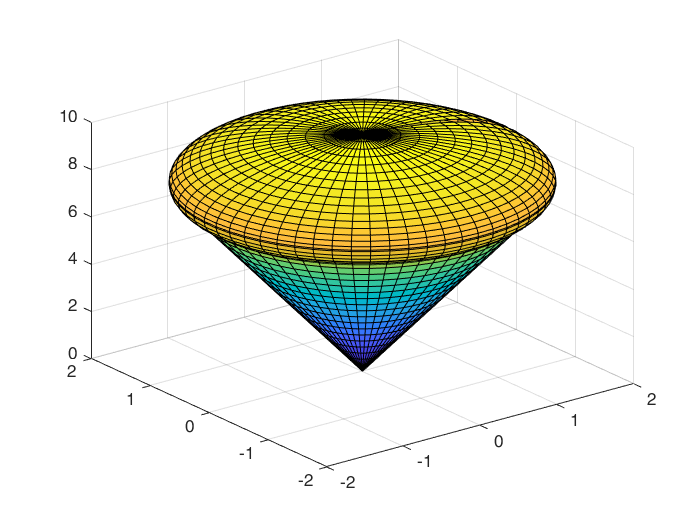

%9
close all
t=0:0.1:2*pi;
r=0:0.1:2;
[T,R]=meshgrid(t,r);
X=R.*cos(T);
Y=R.*sin(T);
Z=4*R;
surf(X,Y,Z)
hold on
t=0:0.1:2*pi;
R=2;
phi=0:0.1:pi;
[T,P]=meshgrid(t,phi);
X=R.*cos(T).*sin(P);
Y=R.*sin(T).*sin(P);
Z=R.*cos(P)+8;
surf(X,Y,Z)